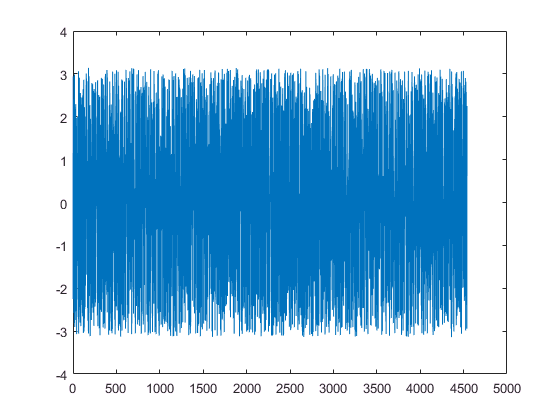

load controlsyncnaomi.mat
load controlsyncrachel.mat
Fs= 100;
plot(fftshift(angle(fft(controlsyncnaomi(:,6)))))

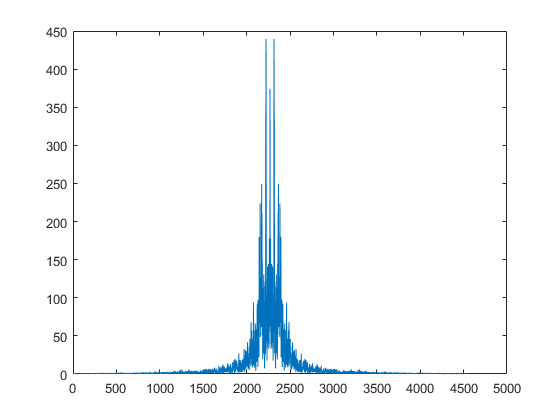

plot(abs(fftshift(fft(controlsyncnaomi(:,6)))))


[N_control, t_control, f_control, mag_control, phase_control, bpm_control] = findbpmphase('controlsyncnaomi.mat', Fs, 'accel', 'y', 1, length(controlsyncnaomi));

lower_threshold = 2.8709

upper_threshold = 5.7417

plot(f_control, phase_control)
hold on
[N_controlr, t_controlr, f_controlr, mag_controlr, phase_controlr, bpm_controlr] = findbpmphase('controlsyncrachel.mat', Fs, 'accel', 'y', 1, length(controlsyncrachel));

lower_threshold = 3.9308

upper_threshold = 7.8616

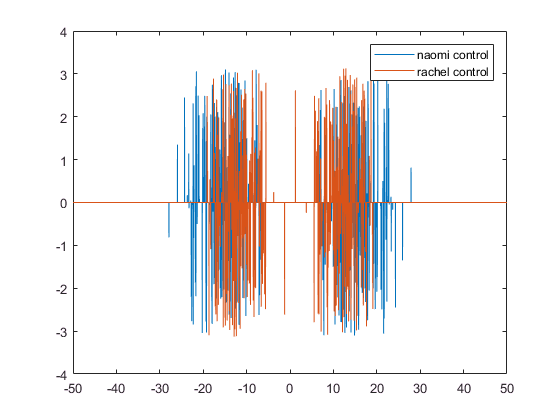

plot(f_controlr, phase_controlr)
hold off
legend('naomi control', 'rachel control')

load controlchaosnaomi.mat
load controlchaosrachel.mat

[N_chaos, t_chaos, f_chaos, mag_chaos, phase_chaos, bpm_chaos] = findbpmphase('controlchaosnaomi.mat', Fs, 'accel', 'y', 1, length(controlchaosnaomi));

lower_threshold = 2.5413

upper_threshold = 5.0825

plot(f_chaos, phase_chaos)
hold on
[N_chaosr, t_chaosr, f_chaosr, mag_chaosr, phase_chaosr, bpm_chaosr] = findbpmphase('controlchaosrachel.mat', Fs, 'accel', 'y', 1, length(controlchaosrachel));

lower_threshold = 6.0687

upper_threshold = 12.1375

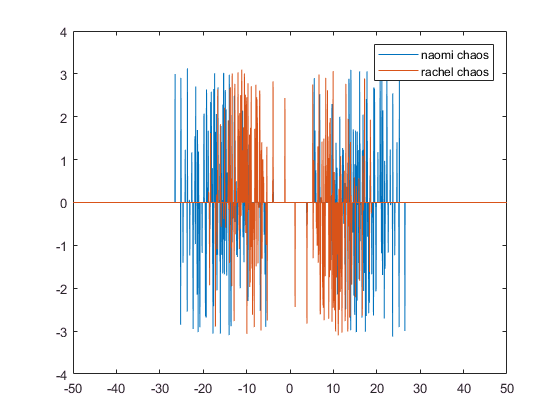

plot(f_chaosr, phase_chaosr)
hold off
legend('naomi chaos', 'rachel chaos')

load onthefloornaomi.mat
load onthefloorrachel.mat

[N_otf, t_otf, f_otf, mag_otf, phase_otf, bpm_otf] = findbpmphase('onthefloornaomi.mat', Fs, 'accel', 'y', 1, length(onthefloornaomi));

lower_threshold = 80.0122

upper_threshold = 160.0245

[N_otfr, t_otfr, f_otfr, mag_otfr, phase_otfr, bpm_otfr] = findbpmphase('onthefloorrachel.mat', Fs, 'accel', 'y', 1, length(onthefloorrachel));

lower_threshold = 86.1399

upper_threshold = 172.2798

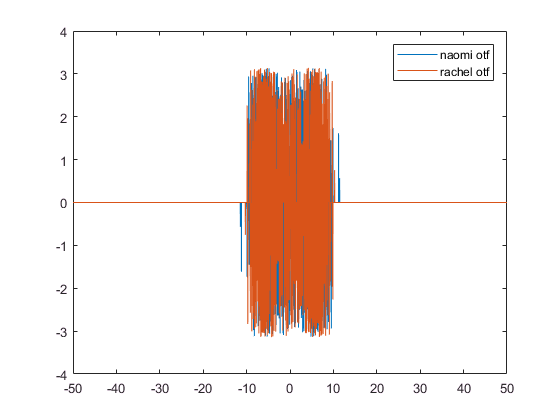

plot(f_otf, phase_otf)
hold on
plot(f_otfr, phase_otfr)
hold off
legend('naomi otf', 'rachel otf')

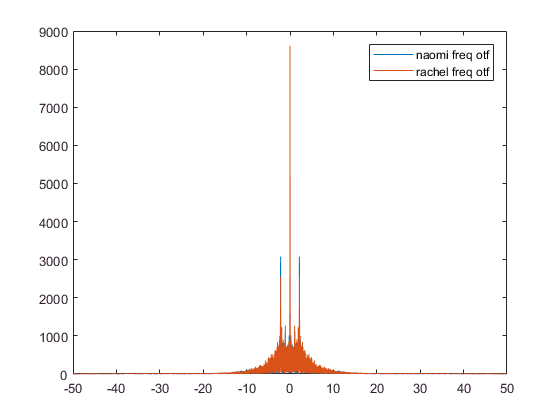


plot(f_otf, mag_otf)
hold on
plot(f_otfr, mag_otfr)
legend('naomi freq otf', 'rachel freq otf')
hold off

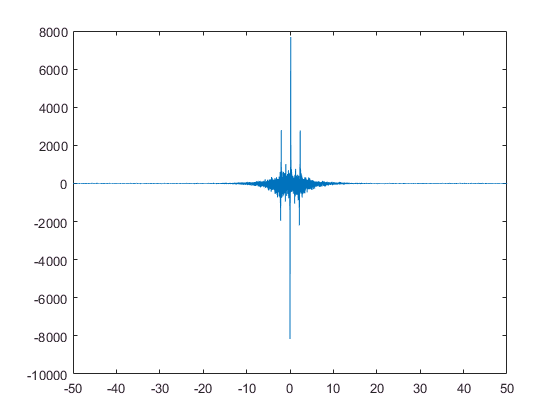


diff = mag_otf(1:length(mag_otfr)) - mag_otfr;
plot(f_otfr, diff)

function [N, t, f, mag, phase, bpm] = findbpmphase(filename, Fs, sensor, direction, start, final)
    file1 = cell2mat(struct2cell(load(filename)));
    file = file1(start:final,:);
    N = length(file(:,1));
    t = linspace(0,N/Fs,N);
    f = linspace(-Fs/2, Fs/2 - Fs/N, N) + Fs/(2*N)*mod(N,2);
    if strcmp(sensor,'accel')
        if strcmp(direction,'x')
            dir = 6;
        elseif strcmp(direction,'y')
            dir = 5;
        elseif strcmp(direction,'z')
            dir = 7;
        else
            dir = 5;
        end
    elseif strcmp(sensor,'gyro')
        if strcmp(direction,'x')
            dir = 3;
        elseif strcmp(direction,'y')
            dir = 2;
        elseif strcmp(direction,'z')
            dir = 4;
        else
            dir = 2;
        end
    end
    mag = fftshift(abs(fft(file(:,dir))));
    cp = fft(file(:,dir));
    lower_threshold = max(abs(fft(file(:,dir))))/100
    upper_threshold = max(abs(fft(file(:,dir))))/50
    clean_phase = abs(fft(file(:,dir)));
    lower_indeces = find(clean_phase < lower_threshold);
    upper_indeces = find(clean_phase > upper_threshold);
    cp(lower_indeces) = 0;
    cp(upper_indeces) = 0;
    phase = angle(fftshift(cp));
 
    positive = mag(f > 0.3);
    H = max(positive);
    bps = find(mag == H);
    bpm = abs(f(bps(1)))*60;
end